# Production and tank models

clear all; clc; close all;

### Define constants

CtoK = 273.15;
EH2 = 285.84e3;         %[J/mol]
F = 96485.3329;         %[C/mol]
ncell = 20;
R = 8.3145;             %[J/(K*mol)]
Ttank = 20 + CtoK;      %[K]
Vtank = 1.6;            %[m^3]

### Import data

to_import = ["eff1","eff2","eff3","eff4","eff5"];

m = struct("control",[])

m = struct with fields:
    control: []


m.time = [];
m.I_stack = [];
m.U_stack = [];
m.T_in = [];
m.T_out = [];
m.tankP = [];
for c = 1:length(to_import)
    tdms = TDMS_getStruct(convertStringsToChars(to_import(c)+ ".tdms"))
    measurements = tdms.Group1;
    m(:).control = [m.control measurements.Control.data];
    m(:).time = [m.time measurements.Time.data];
    m(:).I_stack  =[m.I_stack measurements.I_Stack.data];
    m(:).U_stack = [m.U_stack measurements.U_Stack.data];
    m(:).T_in = [m.T_in measurements.O2_T_In.data];
    m(:).T_out = [m.T_out measurements.O2_T_Out.data];
    m(:).tankP = [m.tankP measurements.H2_PrProd.data];
    fprintf(c + ".tdms")
end

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


1.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


2.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


3.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


4.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


5.tdms


m(:).T = (m.T_in+m.T_out)./2; %average stack temperature

m.Pin = m.I_stack .* m.U_stack;
m.Pout = EH2.*m.I_stack.*ncell./(2.*F);

tank_filling_run = m.time>2000 & m.time<16000;

### Plot the experiment and smoothed data

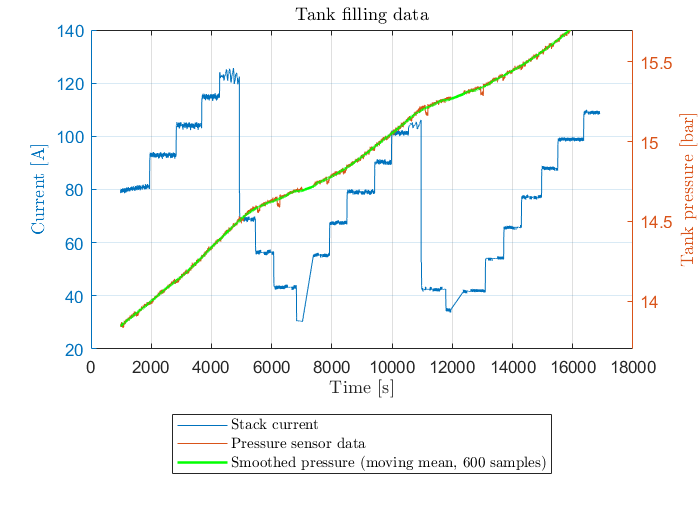

deg50 = 1000:7039;
deg40 = 7400:11965;
deg30 = 12375:16900;
degfull = [deg50 deg40 deg30];
figure;
yyaxis left
yyaxis left
plot(m.time(degfull),m.I_stack(degfull))
hold on
ylabel("Current [A]","Interpreter","latex")
grid on
yyaxis right
ylim([13.7 15.7])
title("Tank filling data","Interpreter","latex")
ylabel("Tank pressure [bar]","Interpreter","latex")
xlabel("Time [s]","Interpreter","latex")
m.tank_smooth_P = smoothdata(m.tankP,"movmean",600); 
plot(m.time(degfull),m.tankP(degfull))
plot(m.time(degfull),m.tank_smooth_P(degfull),"-g","LineWidth",1.5)
legend("Stack current","Pressure sensor data","Smoothed pressure (moving mean, 600 samples)","interpreter", "latex","Location","southoutside")
hold off

### Calculate charge and pressure differences at operating points

bar_to_Pa = 100000;
m.tank_smooth_P = m.tank_smooth_P.*bar_to_Pa;
operating_point_start = [1202, 2315, 3300, 3900, 4500, 5150,5750,6521 7543, 8100, 8847, 9600, 10244, 12699, 13300, 13764, 14351, 14994, 15547, 16376];
interval_length = 300; %5 minutes
for i = 1:length(operating_point_start)
        sample_slice = [operating_point_start(i):operating_point_start(i)+interval_length];
        delta_p(i) = m.tank_smooth_P(int64(sample_slice(end)))-m.tank_smooth_P(int64(sample_slice(1)));
        delta_Q(i) = trapz(m.time(int64(sample_slice)),m.I_stack(int64(sample_slice)));
end

### Calculate regression

k = ncell*R*Ttank/(2*F*Vtank);
Y = delta_p';
X = k*delta_Q';
eta_Faraday_regression = X\Y;

### Check regression using custom-made fit

[fittedmodel, gof] = tankfill_fit(k.*delta_Q,delta_p)

fittedmodel =      General model:
     fittedmodel(dQ) = eff_faraday_builtin.*dQ
     Coefficients (with 95% confidence bounds):
       eff_faraday_builtin =       1.036  (0.9931, 1.078)

gof = struct with fields:
           sse: 2.4789e+06
       rsquare: 0.9009
           dfe: 19
    adjrsquare: 0.9009
          rmse: 361.2057


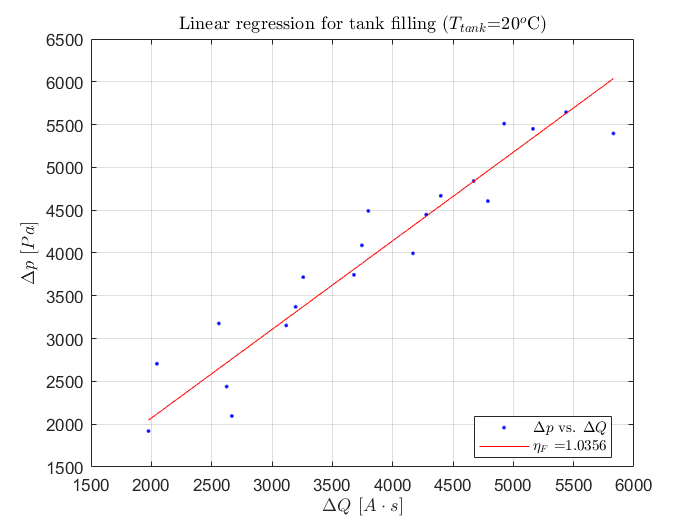

title("Linear regression for tank filling ($T_{tank}$=" + num2str(Ttank-CtoK) + "$^o$C)","Interpreter","latex")

eta_Faraday_builtin = fittedmodel.eff_faraday_builtin

eta_Faraday_builtin = 1.0356

eta_Faraday_regression

eta_Faraday_regression = 1.0356

### Simulation of tank pressure

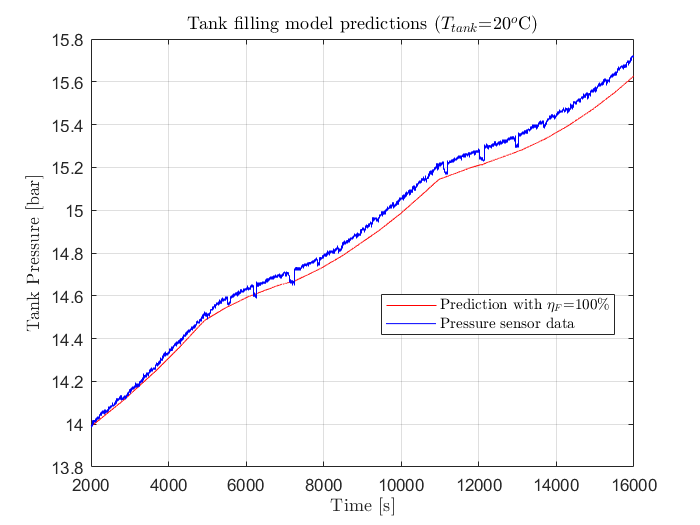

close all;
stack_current = timeseries(m.I_stack(tank_filling_run),m.time(tank_filling_run));
tank_pressure = timeseries(m.tankP(tank_filling_run),m.time(tank_filling_run));

output = sim("filling_model.slx");

plot(output.tank_pressure_predict,"r-","displayname","Prediction with $\eta_F$=100\%")
hold on
%plot(output.tank_pressure_predict_eta,"g-","displayname","Prediction with computed $\eta_F$ = " + num2str(eta_Faraday_builtin.*100) + "\%")
plot(output.tank_pressure_real,"b-","displayname","Pressure sensor data")
legend("interpreter","latex","Location","best")
ylabel("Tank Pressure [bar]","interpreter","latex")
xlabel("Time [s]","Interpreter","latex")
title("Tank filling model predictions ($T_{tank}$=" + num2str(Ttank-CtoK) + "$^o$C)","interpreter","latex")
grid on
hold off

## Repeat everything at 30$^o$C

close all;
clear fittedmodel; clear gof;
Ttank = 30 + CtoK;

### Calculate regression

k = ncell*R*Ttank/(2*F*Vtank);
Y = delta_p';
X = k*delta_Q';
eta_Faraday_regression = X\Y;

### Check regression using custom-made fit

figure;
[fittedmodel, gof] = tankfill_fit(k.*delta_Q,delta_p)

fittedmodel =      General model:
     fittedmodel(dQ) = eff_faraday_builtin.*dQ
     Coefficients (with 95% confidence bounds):
       eff_faraday_builtin =       1.001  (0.9603, 1.043)

gof = struct with fields:
           sse: 2.4789e+06
       rsquare: 0.9009
           dfe: 19
    adjrsquare: 0.9009
          rmse: 361.2057


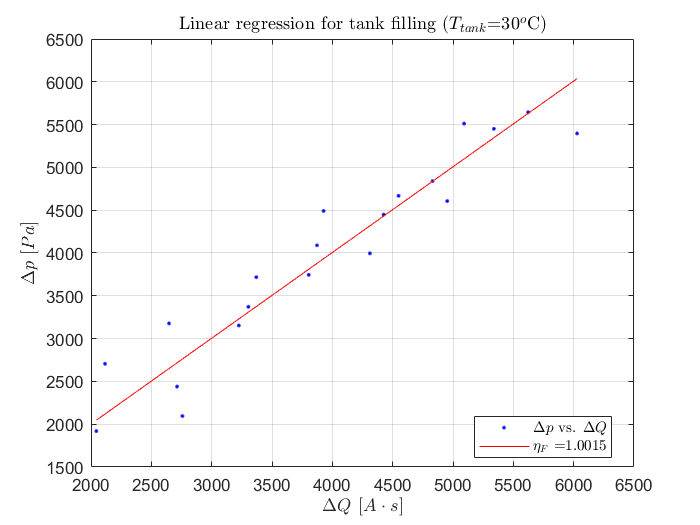

title("Linear regression for tank filling ($T_{tank}$=" + num2str(Ttank-CtoK) + "$^o$C)","Interpreter","latex")

eta_Faraday_builtin = fittedmodel.eff_faraday_builtin

eta_Faraday_builtin = 1.0015

eta_Faraday_regression

eta_Faraday_regression = 1.0015

### Simulation of tank pressure

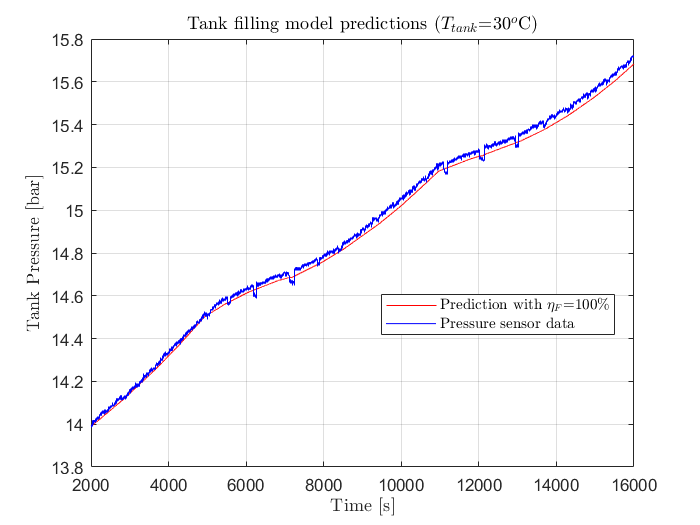

stack_current = timeseries(m.I_stack(tank_filling_run),m.time(tank_filling_run));
tank_pressure = timeseries(m.tankP(tank_filling_run),m.time(tank_filling_run));

output = sim("filling_model.slx");

plot(output.tank_pressure_predict,"r-","displayname","Prediction with $\eta_F$=100\%")
hold on
%plot(output.tank_pressure_predict_eta,"g-","displayname","Prediction with computed $\eta_F$ = " + num2str(eta_Faraday_builtin.*100) + "\%")
plot(output.tank_pressure_real,"b-","displayname","Pressure sensor data")
legend("interpreter","latex","Location","best")
ylabel("Tank Pressure [bar]","interpreter","latex")
xlabel("Time [s]","Interpreter","latex")
title("Tank filling model predictions ($T_{tank}$=" + num2str(Ttank-CtoK) + "$^o$C)","interpreter","latex")
grid on
hold off